clc
clear
v0 = input("Velocidad inicial en m/s: ");  %Velocidad inicial tiro 1
theta = input("Ángulo de tiro en grados: "); %Ángulo tiro 1
theta = theta*3.1416/180; %conversión a radianes
g = 9.81; %Gravedad 
h = input("Altura del volcán en metros: ") %Altura inicial

h = 5


n1theta= theta+0.1745 %Ángulo tiro 2

n1theta = 0.9599

n2theta = theta - 0.1745 %Ángulo tiro 3

n2theta = 2.3562


v1 = v0*1.1 %Velocidad inicial tiro 2

v1 = 22

v2 = v0*1.3 %Velocidad inicial tiro 3

v2 = 26


%Sin viento
t = ((v0*sin(theta))+((v0*sin(theta))^2+2*h*g)^0.5)/g; %Tiempo tiro 1
tn1 = ((v1*sin(n1theta))+((v1*sin(n1theta))^2+2*h*g)^0.5)/g; %Tiempo tiro 2
tn2 = ((v2*sin(n2theta))+((v2*sin(n2theta))^2+2*h*g)^0.5)/g %Tiempo tiro 3

tn2 = 4.0028


t1 = 0:0.01:t; %Tiempo tiro 1
t11 = 0:0.01:tn1; %Tiempo tiro 2
t12 = 0:0.01:tn2; %Tiempo tiro 3

x = v0*cos(theta).*t1; %Trayectoria en x tiro 1
y = h + (tan(theta).*x)-(0.5*g/(v0*cos(theta)).^2).*(x.^2); %Trayectoria en y tiro 1

x1 = v1*cos(n1theta).*t11; %Trayectoria en x tiro 2
y1 = h + (tan(n1theta).*x1)-(0.5*g/(v1*cos(n1theta)).^2).*(x1.^2); %Trayectoria en y tiro 2

x2 = v2*cos(n2theta).*t12 %Trayectoria en x tiro 3

x2 =          0   -0.1838   -0.3677   -0.5515   -0.7354   -0.9192   -1.1031   -1.2869   -1.4708   -1.6546   -1.8385   -2.0223   -2.2062   -2.3900   -2.5739   -2.7577   -2.9416   -3.1254   -3.3093   -3.4931   -3.6770   -3.8608   -4.0447   -4.2285   -4.4124   -4.5962   -4.7801   -4.9639   -5.1478   -5.3316   -5.5155   -5.6993   -5.8832   -6.0670   -6.2509   -6.4347   -6.6186   -6.8024   -6.9863   -7.1701   -7.3540   -7.5378   -7.7216   -7.9055   -8.0893   -8.2732   -8.4570   -8.6409   -8.8247   -9.0086


y2 = h + (tan(n2theta).*x2)-(0.5*g/(v1*cos(n2theta)).^2).*(x2.^2); %Trayectoria en y tiro 3
y2 = max(0,y2);

%Con viento

T = (2 * v0 * sin(theta) / g) + (2 * v0 / g) * ((v0 * sin(theta) / g) + sqrt((v0 * sin(theta) / g)^2 + 2 * h / g)); %Tiempo tiro 1
Tn1 = (2 * v1 * sin(n1theta) / g) + (2 * v1 / g) * ((v1 * sin(n1theta) / g) + sqrt((v1 * sin(n1theta) / g)^2 + 2 * h / g)); %Tiempo tiro 2
Tn2 = (2 * v2 * sin(n2theta) / g) + (2 * v2 / g) * ((v2 * sin(n2theta) / g) + sqrt((v2 * sin(n2theta) / g)^2 + 2 * h / g)); %Tiempo tiro 3

t2 = 0:0.01:T; %Tiempo tiro 1
t21 = 0:0.01:Tn1; %Tiempo tiro 2
t22 = 0:0.01:Tn2; %Tiempo tiro 3


viento = 0.5 %indice de fricción

viento = 0.5000

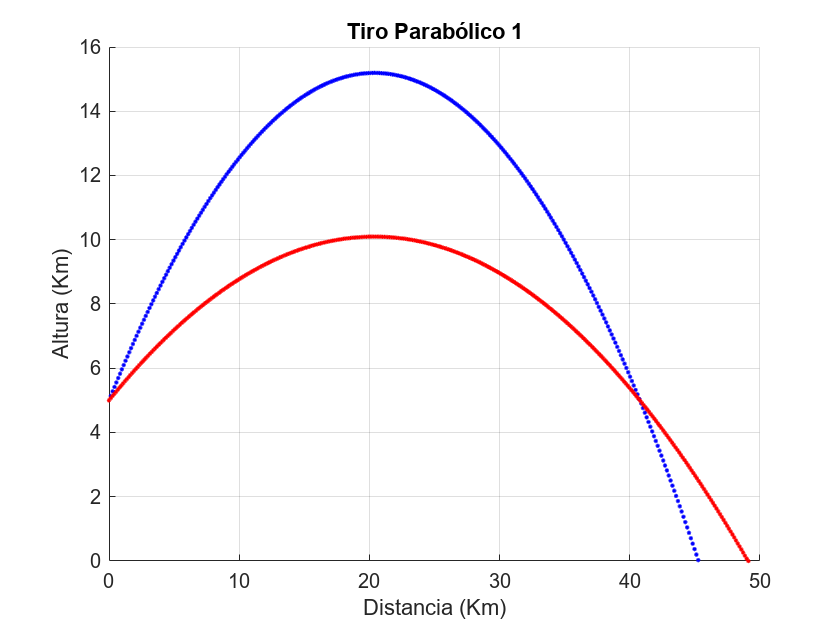


x_v = ((v0*cos(theta))-viento).*t2; %Trayectoria en x con viento tiro 1
y_v = -(-viento.*((tan(theta).*x_v)-(0.5*g/(v0*cos(theta)).^2).*(x_v.^2))) + h; %Trayectoria en y con viento tiro 1
y_v = max(0,y_v);

x_v1 = ((v1*cos(n1theta))-viento).*t21; %Trayectoria en x con viento tiro 2
y_v1 = -(-viento.*((tan(n1theta).*x_v1)-(0.5*g/(v1*cos(n1theta)).^2).*(x_v1.^2))) + h; %Trayectoria en y con viento tiro 2
y_v1 = max(0,y_v1);

x_v2 = ((v2*cos(n2theta))-viento).*t22; %Trayectoria en x con viento tiro 3
y_v2 = -(-viento.*((tan(n2theta).*x_v2)-(0.5*g/(v2*cos(n2theta)).^2).*(x_v2.^2))) + h; %Trayectoria en y con viento tiro 3
y_v2 = max(0,y_v2);

%Animación

figure; 
hold on

%Tiro 1 sin viento
for i = 1:numel(y)
    if y(i) <= 0
            plot(x(i),y(i),'.','color','b') 
        drawnow
        break
    else
        plot(x(i),y(i),'.','color','b')
        drawnow
        pause(0.01);
    end
end

%Tiro 1 con viento
for j = 1:numel(y_v)
    if y_v(j) <= 0
        plot(x_v(1:j), y_v(1:j), '.', 'color', 'r'); 
        drawnow
        break
    else
        plot(x_v(j), y_v(j), '.', 'color', 'r');
        drawnow
        pause(0.01);
    end
end

xlabel('Distancia (m)');
ylabel('Altura (m)');
title('Tiro 1');
grid on;

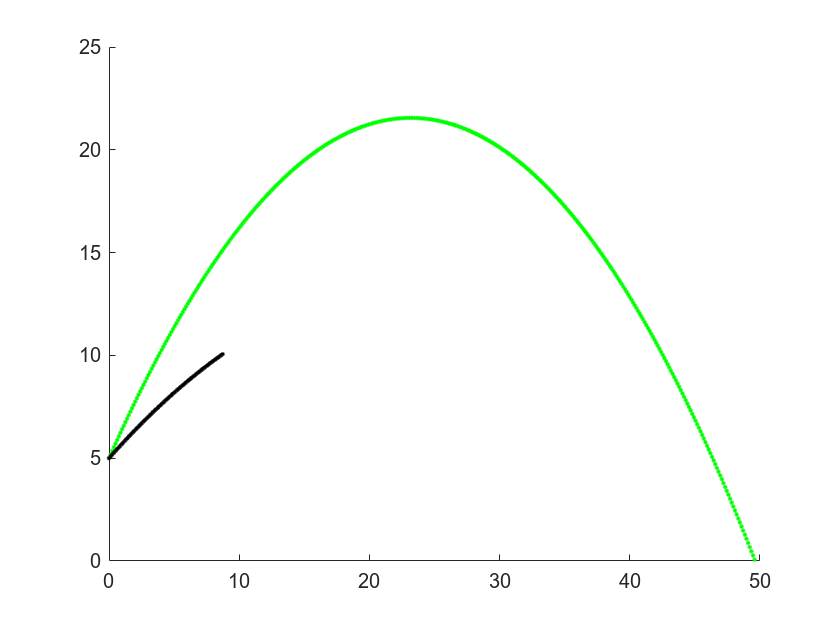


figure;
hold on
%Tiro 2 sin viento
for i = 1:numel(y1)
    if y1(i) <= 0
        plot(x1(i),y1(i),'.','color','g')
        drawnow
        break
    else
        plot(x1(i),y1(i),'.','color','g')
        drawnow
        pause(0.01);
    end
end

%Tiro 2 con viento
for j = 1:numel(y_v1)
    if y_v1(j) <= 0
        plot(x_v1(j), y_v(j), '.', 'color', 'k');
        drawnow
        break
    else
        plot(x_v1(j), y_v1(j), '.', 'color', 'k');
        drawnow
        pause(0.01);
    end
end


xlabel('Distancia (m)');
ylabel('Altura (m)');
title('Tiro 2');
grid on;

figure;
hold on
%Tiro 3 sin viento
for i = 1:numel(y2)
    if y2(i) <= 0
        plot(x2(i),y2(i),'.','color','c')
        drawnow
        break
    else
        plot(x2(i),y2(i),'.','color','c')
        drawnow
        pause(0.01);
    end
end

%Tiro 3 con viento
for j = 1:numel(y_v2)
    if y_v2(j) <= 0
        plot(x_v2(1:j), y_v2(1:j), '.', 'color', 'm');
        drawnow
        break
    else
        plot(x_v2(j), y_v2(j), '.', 'color', 'm');
        drawnow
        pause(0.01);
    end
end


%Etiquetas de la gráfica
xlabel('Distancia (m)');
ylabel('Altura (m)');
title('Tiro 3');
grid on;